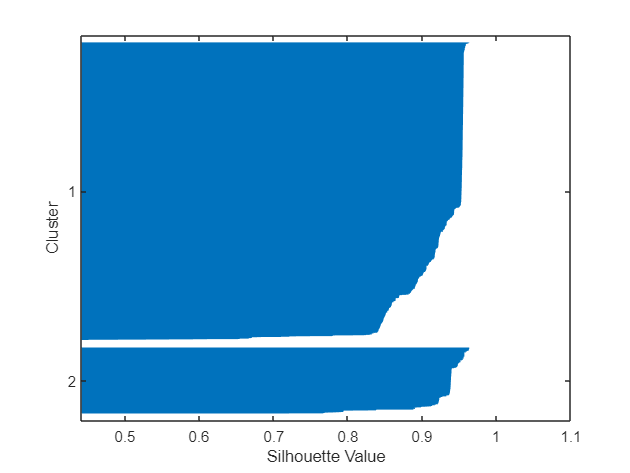

ans = 0.9256

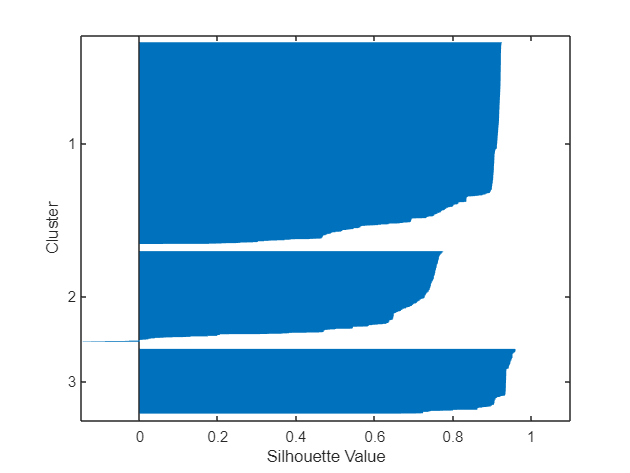

ans = 0.8097

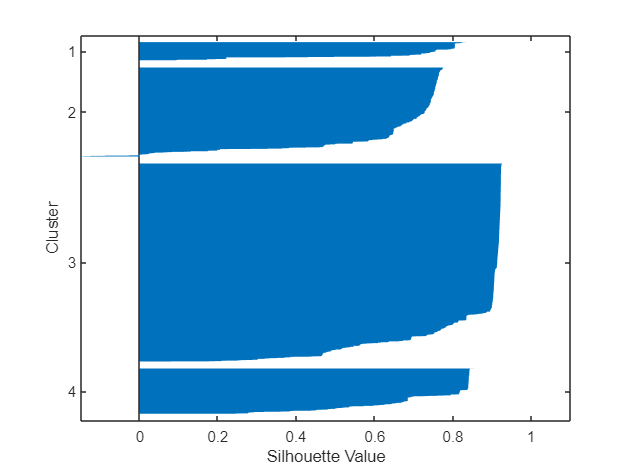

ans = 0.7706

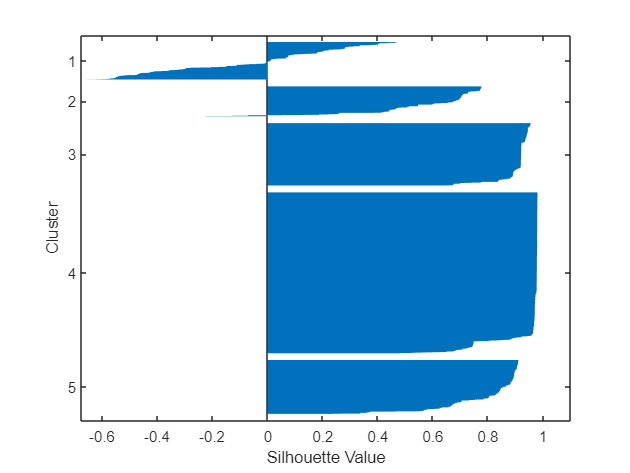

ans = 0.7787

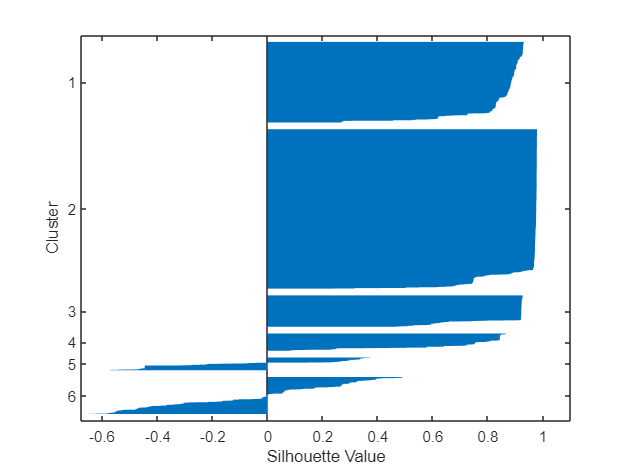

ans = 0.7540

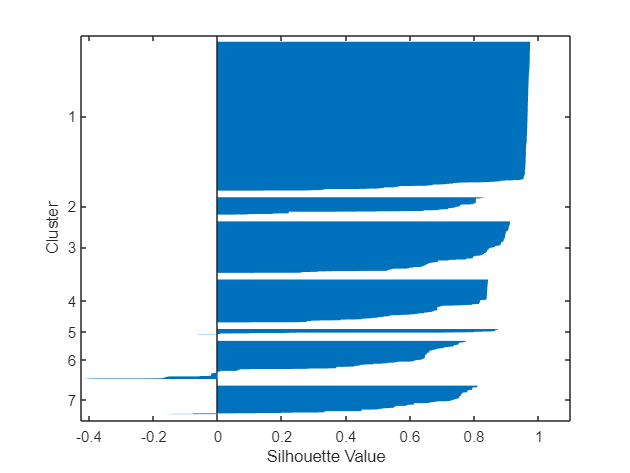

ans = 0.7880

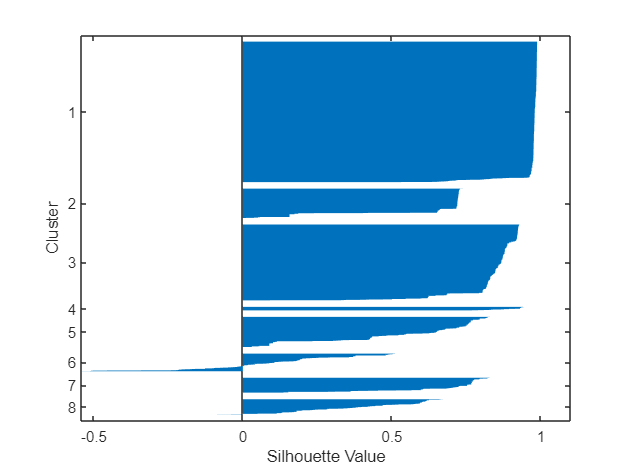

ans = 0.7823

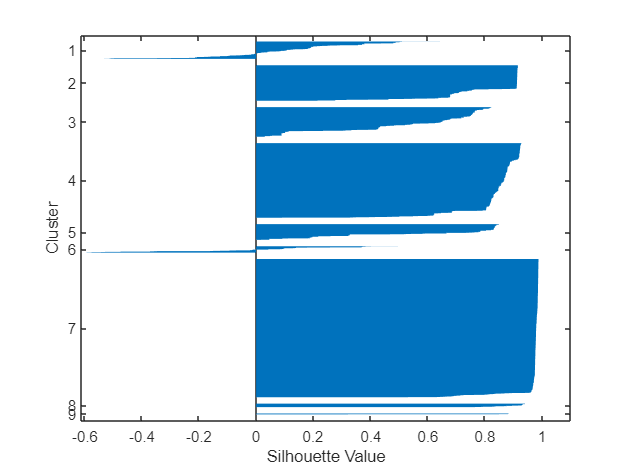

ans = 0.7994

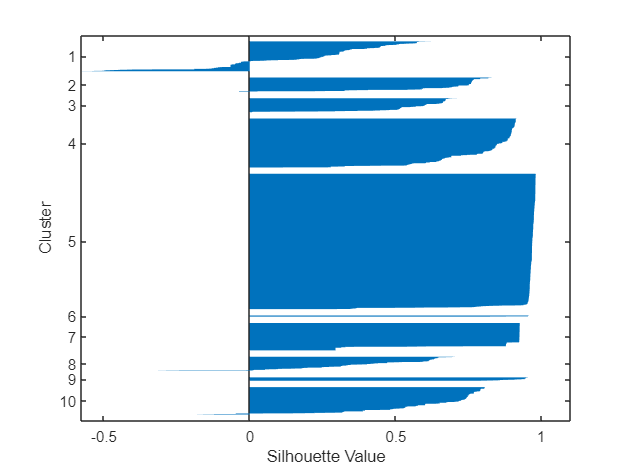

ans = 0.7621

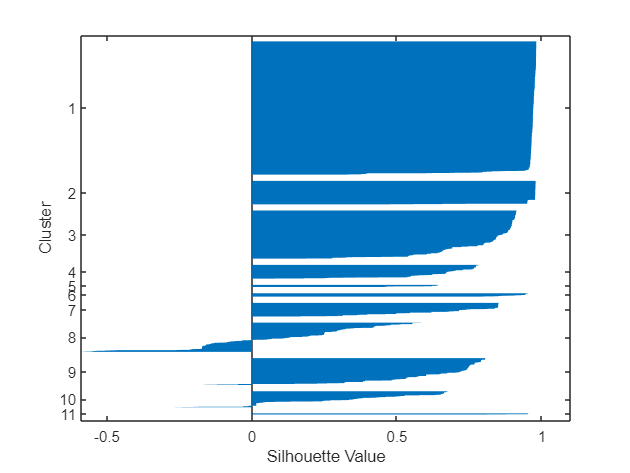

ans = 0.7638

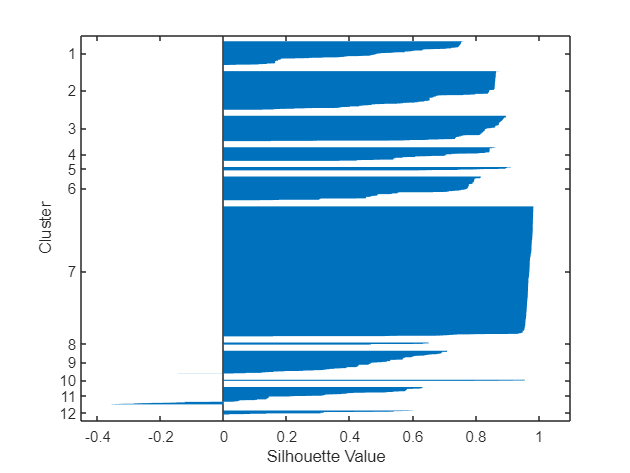

ans = 0.7593

%cleaning workspace
clear;

% Load dataset
load Dataset_task2.mat;
%Dataset presenta dati mancanti o errati e colonna 19 duplicata di 18
short_matrix_no_id(:,19) = [];
short_matrix_no_id = fillmissing(short_matrix_no_id,"next");
%short_matrix_no_id = normalize(short_matrix_no_id);

% BUS LINE
bus_line = short_matrix_no_id(:,[1, 2:6, 8:9, 15, 16:17]);

%Vehicle ID
vehicle_id = short_matrix_no_id(:,[1, 6:8, 11:15, 18]);

%driver id
driver_id = short_matrix_no_id(:, [1, 6, 8, 15]);

% Calcolo del numero di cluster
unique_driver = unique(short_matrix_no_id(:,8),"rows"); %229 istanze
unique_vehicle = unique(short_matrix_no_id(:,6),"rows"); %105 istanze
unique_line = unique(short_matrix_no_id(:,1),"rows"); % 87 istanze


% Range of number of clusters
k_values = 2:12;

% Initialize array to store percentage variance for each matrix
variance_pct_driver = zeros(size(k_values));
variance_pct_vehicle = zeros(size(k_values));
variance_pct_busline = zeros(size(k_values));
mean_silhouette_scores = [];
% Perform k-means clustering for each number of clusters on driver_id
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on driver_id
    [idx_driver, centroids, sumd] = kmeans(driver_id, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_driver(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(driver_id,idx_driver);
    silhouette(driver_id,idx_driver);

    mean(sil_scores)
    
end

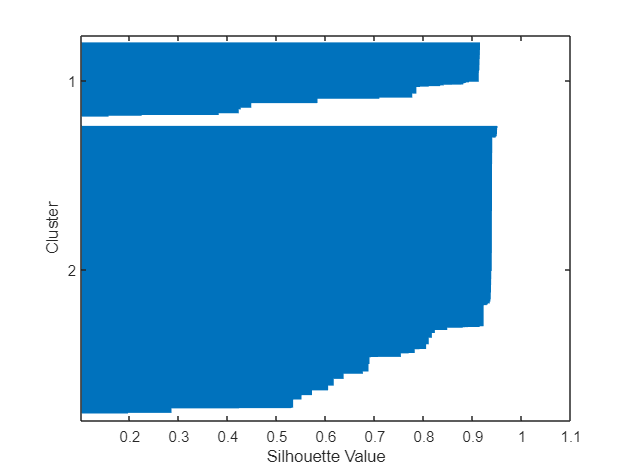

ans = 0.8340

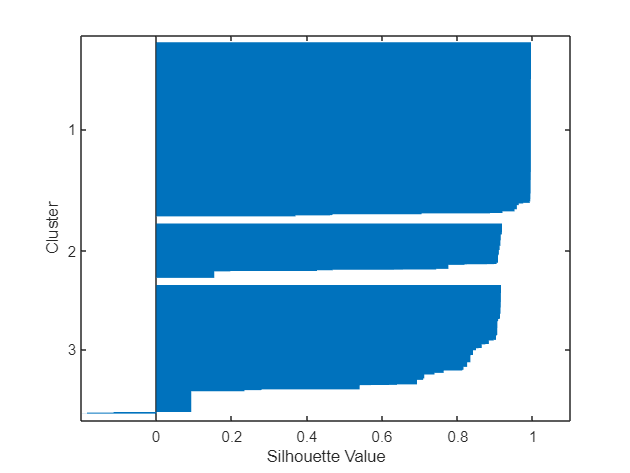

ans = 0.8538

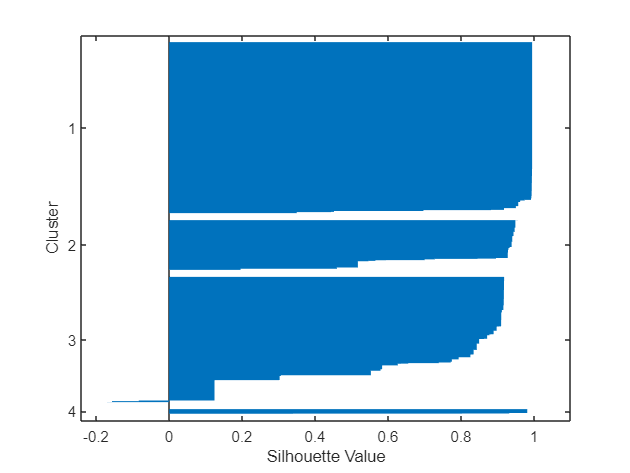

ans = 0.8600

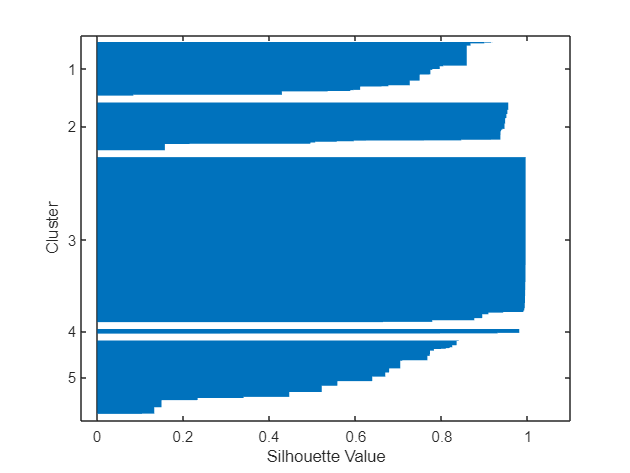

ans = 0.8340

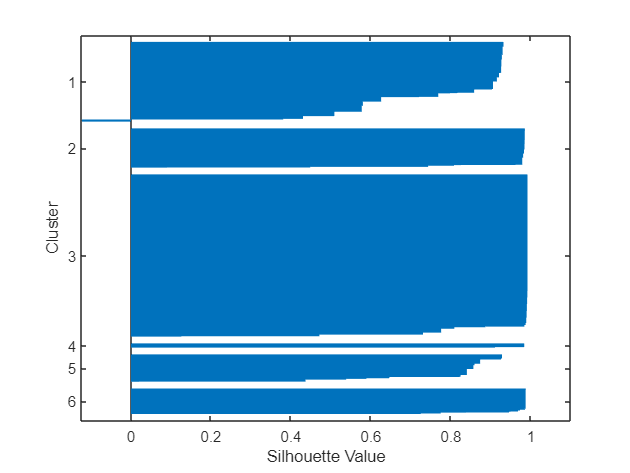

ans = 0.9128

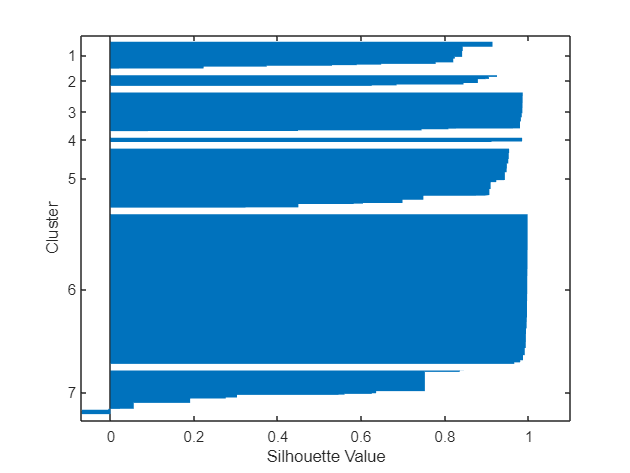

ans = 0.8752

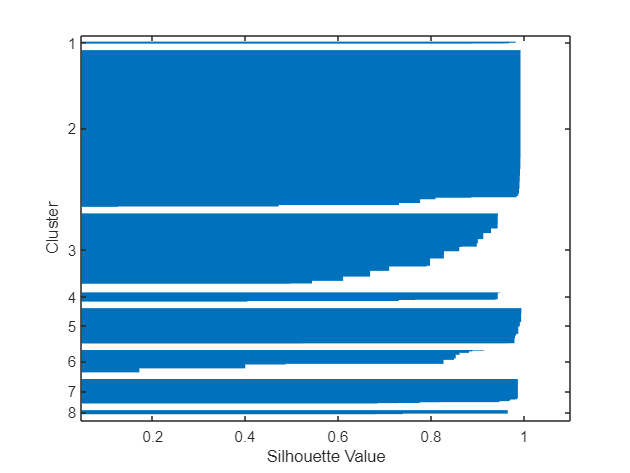

ans = 0.9117

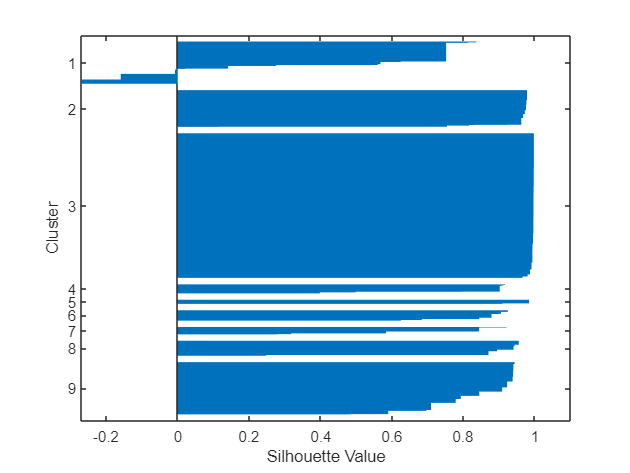

ans = 0.8641

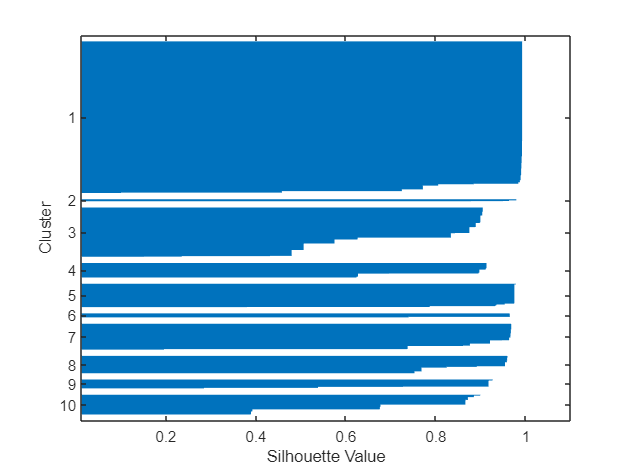

ans = 0.8985

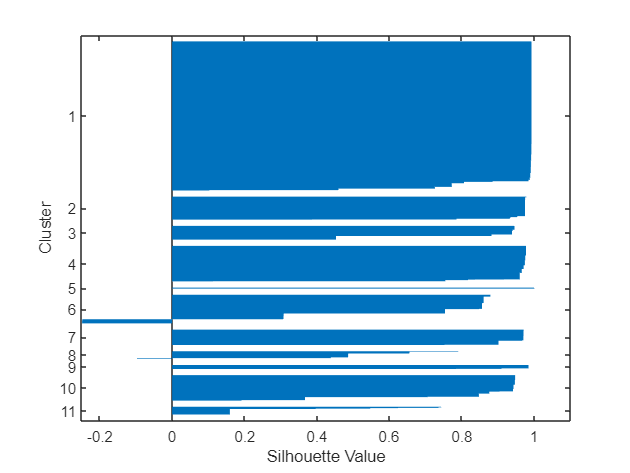

ans = 0.8857

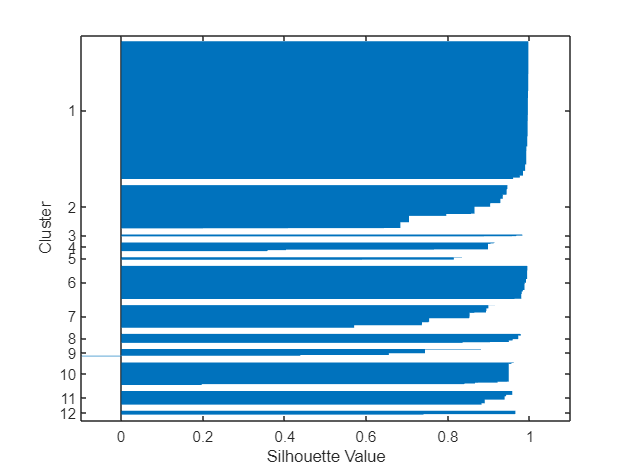

ans = 0.9313


% Perform k-means clustering for each number of clusters on vehicle_id
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on vehicle_id
    [idx_vehicle, centroids, sumd] = kmeans(vehicle_id, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_vehicle(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(vehicle_id,idx_vehicle);
    silhouette(vehicle_id,idx_vehicle);
    mean(sil_scores)
    
end

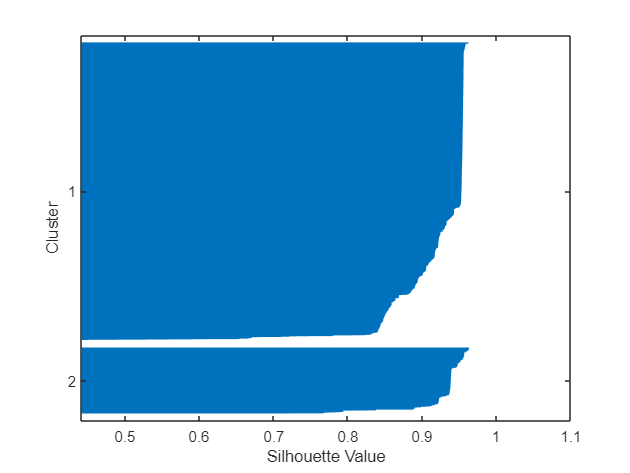

ans = 0.9253

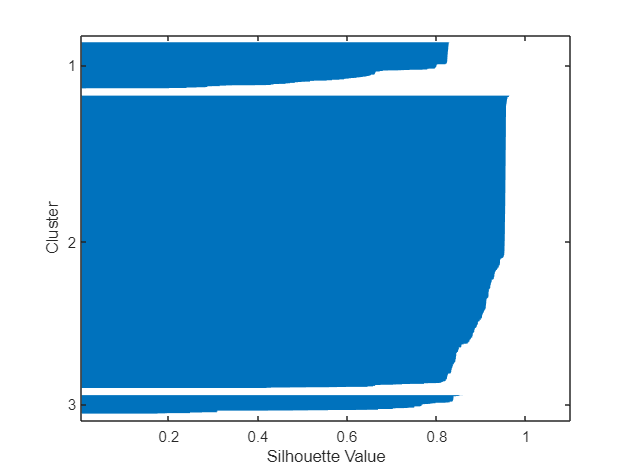

ans = 0.8805

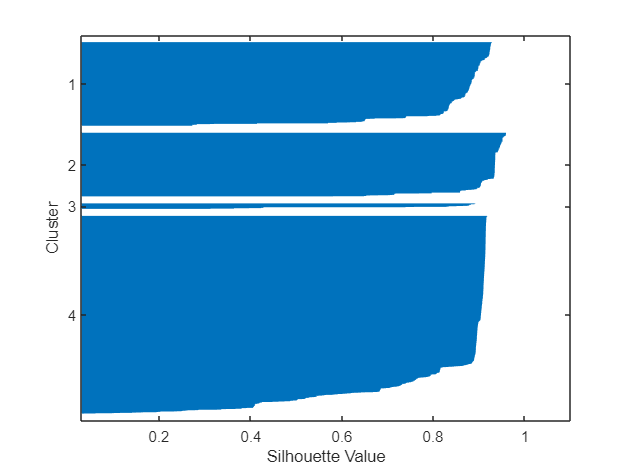

ans = 0.8503

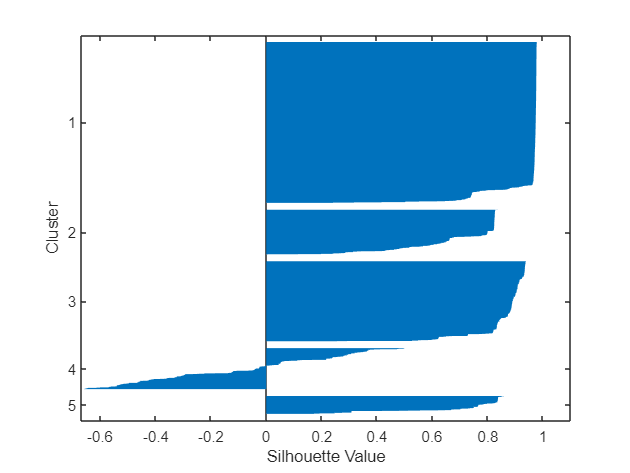

ans = 0.7621

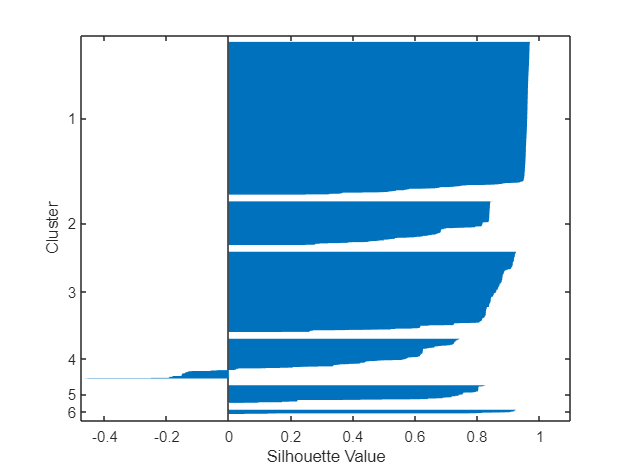

ans = 0.8019

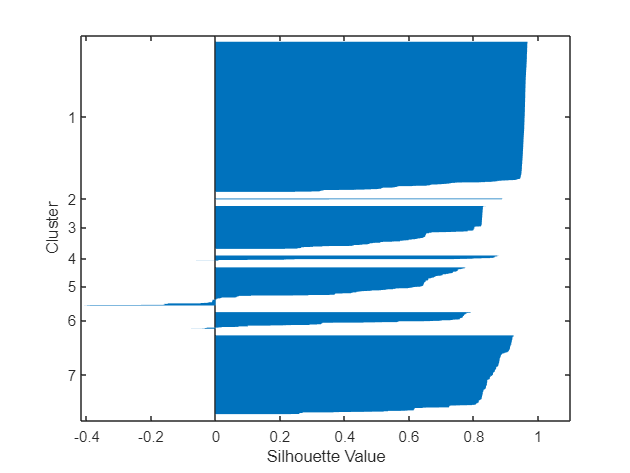

ans = 0.7965

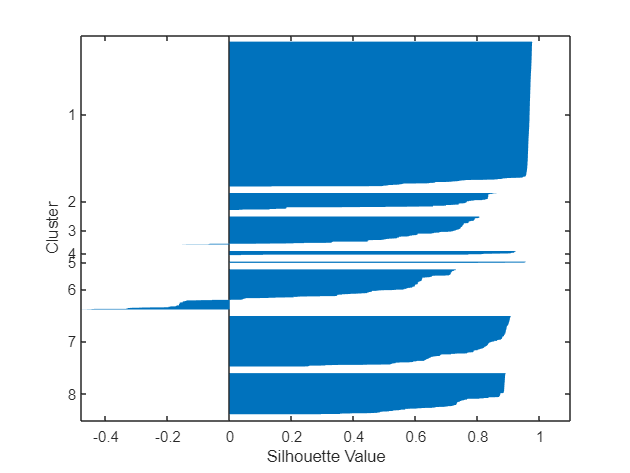

ans = 0.7883

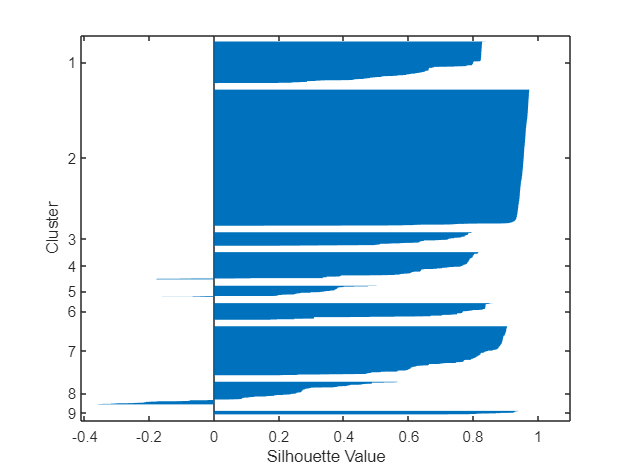

ans = 0.7662

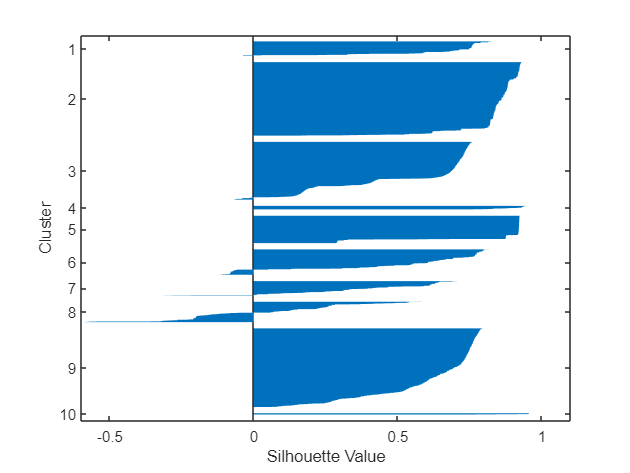

ans = 0.6203

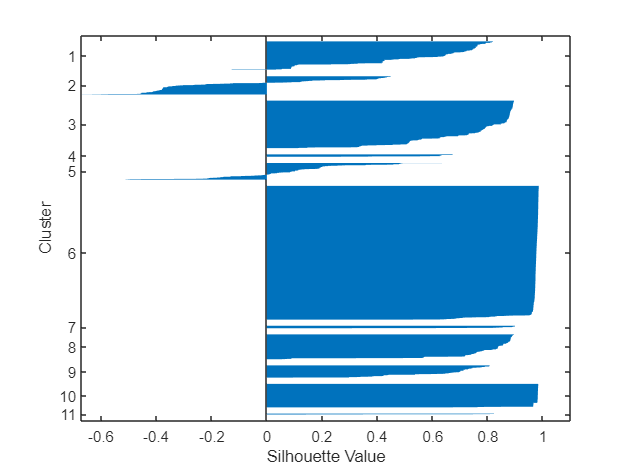

ans = 0.7508

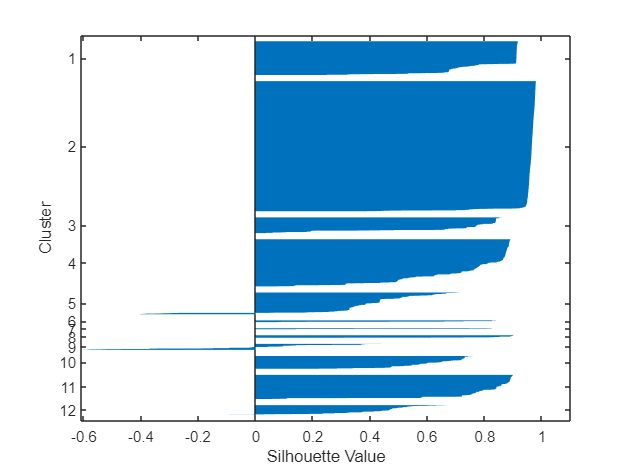

ans = 0.7863


% Perform k-means clustering for each number of clusters on bus_line
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on bus_line
    [idx_line,centroids, sumd] = kmeans(bus_line, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_busline(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(bus_line,idx_line);
    silhouette(bus_line,idx_line);
    mean(sil_scores)
end

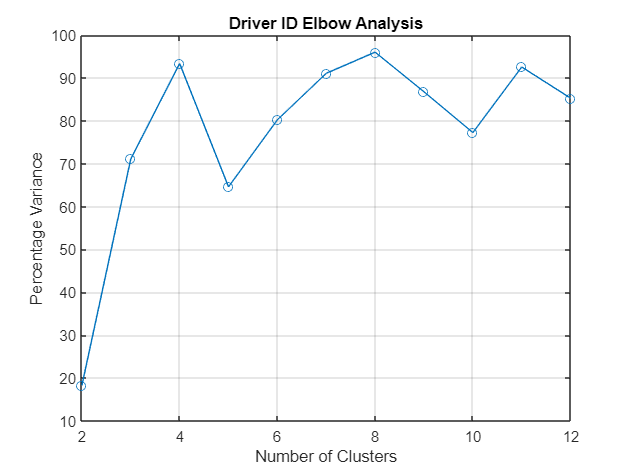


% Plot elbow curves for each matrix separately
figure;
plot(k_values, variance_pct_driver, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Driver ID Elbow Analysis');
grid on;

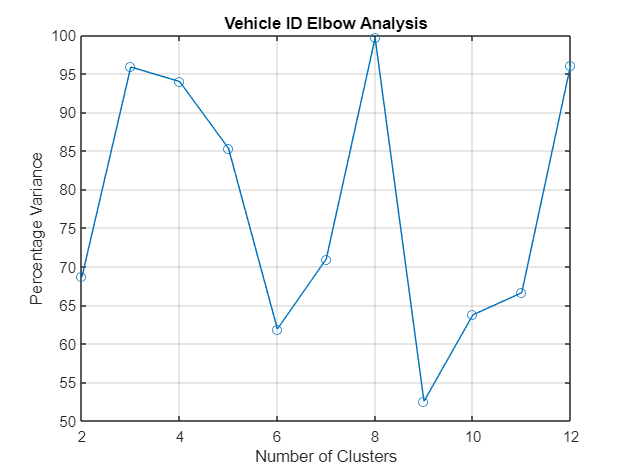


plot(k_values, variance_pct_vehicle, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Vehicle ID Elbow Analysis');
grid on;

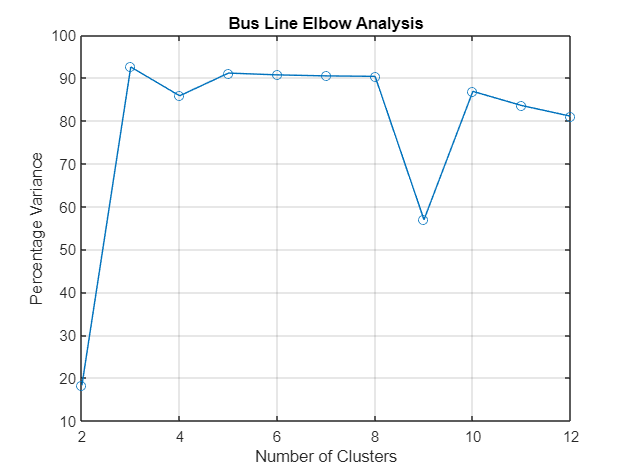


plot(k_values, variance_pct_busline, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Bus Line Elbow Analysis');
grid on;



idx_line = kmeans(bus_line, 5);
idx_vehicle = kmeans(vehicle_id, 6);
idx_driver = kmeans(driver_id, 5);

% Assign a new ID to each cluster
cluster_line_ids = (1:5)';
cluster_vehicle_ids = (1:6)';
cluster_driver_ids = (1:5)';


% Assign a new ID to each cluster
new_ids_line = cluster_line_ids(idx_line);
new_ids_vehicle = cluster_vehicle_ids(idx_vehicle);
new_ids_driver = cluster_driver_ids(idx_driver);

% Replace the original IDs in the dataset with the new IDs
short_matrix_no_id = [short_matrix_no_id, new_ids_line new_ids_vehicle new_ids_driver];
X = short_matrix_no_id;
X(:, [1,6,8]) = [];
Y = short_matrix_no_id(:,15);
% Split data into training and testing sets
train_ratio = 0.7;
train_size = round(train_ratio*size(X,1));
train_idx = randperm(size(X,1),train_size);
test_idx = setdiff(1:size(X,1),train_idx);
X_train = X(train_idx,:);
Y_train = Y(train_idx,:);
X_test = X(test_idx,:);
Y_test = Y(test_idx,:);


% Define neural network
input_size = size(X_train,2);
output_size = 1;
hidden_size = 12;
net = fitnet(hidden_size);
net.trainFcn = 'trainbr'; % Bayesian regulation algorithm
net.divideFcn = 'dividerand'; % Random division of data into training and validation sets
net.divideParam.trainRatio = 0.2; % Training set proportion
net.divideParam.valRatio = 1 - net.divideParam.trainRatio; % Validation set proportion
net.divideParam.testRatio = 0; % No testing set
net.trainParam.max_fail = 20; % Maximum validation failures
net.trainParam.epochs = 1; % Maximum number of epochs
net.trainParam.goal = 1e-5; % Training goal
net.performFcn = 'mse'; % Mean squared error performance function

% Train neural network
[net,tr] = train(net,X_train',Y_train');

% Test neural network
Y_pred = net(X_test');

% Display the covariance matrix and error
covariance_matrix = cov(Y_pred,Y_test);
covariance_matrix

covariance_matrix =     1.0410    2.2558
    2.2558    6.0194


% Calculate the covariance error
cov_error = sum(sum((cov(Y_pred) - Y_test).^2));
'Covariance Error: '+ cov_error

ans = 1.0e+04 *

    5.9988    6.0032    6.0039    6.0018    6.0035    6.0026    6.0018    6.0031    6.0020    6.0022    5.9953    5.9990    6.0035    6.0035    6.0032    6.0035    5.9979    5.9953


"MSE "+mse(net,Y_pred,Y_test')

ans = "MSE 3.0467"

acc = mean(abs(Y_pred-Y_test')<0.02);
disp(['Accuracy: ' num2str(acc)]);

Accuracy: 0.0077572


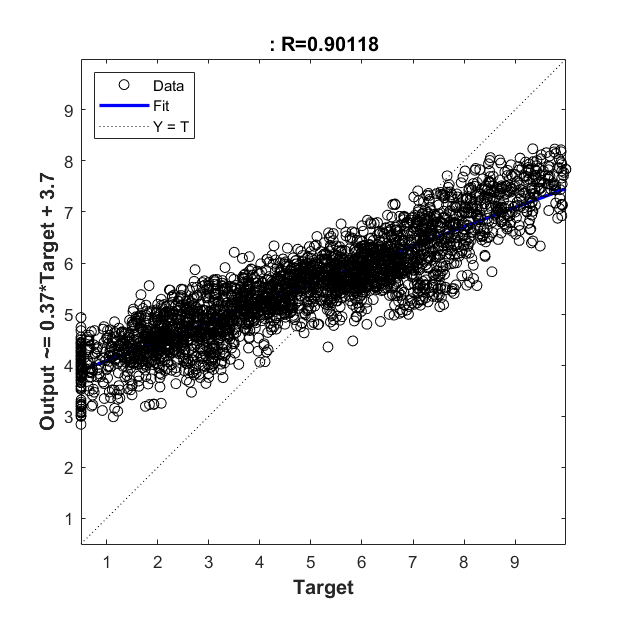


plotregression(Y_test',Y_pred);